# Изучение движения звезд

**Цель:**  рассчитать скорости звезд, определить тип смещения (красное или синее) и построить графики их спектров.

Импортируем данные из файлов.

close all
clear variables
spectra = importdata("spectra.csv");
lambdaStart = importdata("lambda_start.csv");
lambdaDelta = importdata("lambda_delta.csv");
starsNames = importdata("star_names.csv");

Константы.

c = 299792.458; % км/с - скорость света
lambdaStandart = 656.28; % нм - ожидаемая длина волны
text1 = "Пунктир - синее смещение"

text1 = "Пунктир - синее смещение"

text2 = "Сплошной - красное смещение"

text2 = "Сплошной - красное смещение"

Формулs для определения смещения и скорости движения звезды:


$$z=\frac{\lambda_{\textrm{пр}} -\lambda_{\textrm{исп}} }{\lambda_{\textrm{исп}} }$$
 


$$v=z\cdot c$$


Число наблюдений и количество исследуемых звёзд.

nObs = size(spectra, 1);

nStars = size(spectra, 2);

Получениия вектора длин волн **lambda.**

lambdaEnd = lambdaStart + (nObs - 1) * lambdaDelta;

lambda = (lambdaStart : lambdaDelta : lambdaEnd)';

Получение векторов минимальных интенсивностей и их индексов для всех звезд.

[minValue, ind] = min(spectra);

lambdaHa = lambda(ind);

Определение смещения звезд и их скорости движения.

z = (lambdaHa / lambdaStandart) - 1;

speed = z * c;

Построение графиков спектров всех звезд

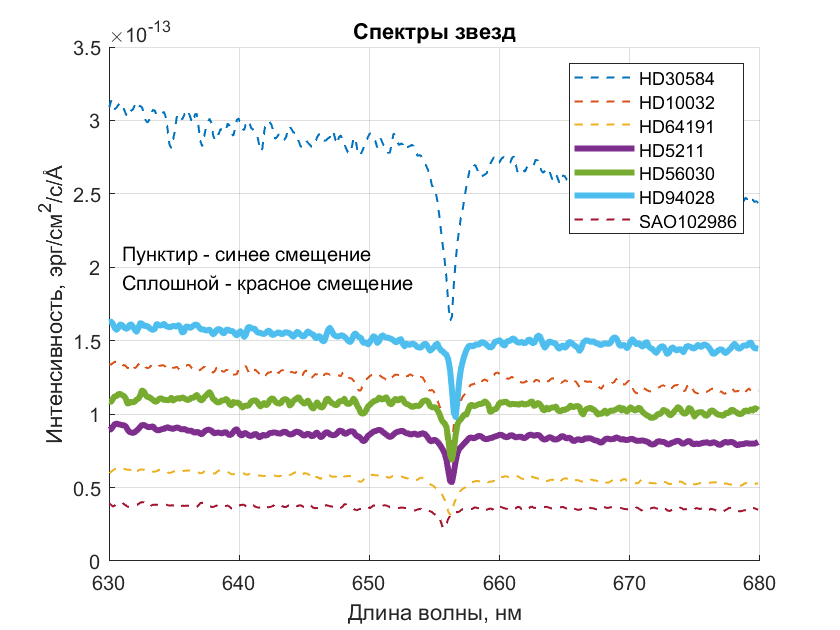

fg1 = figure;
hold on

for i= 1:size(speed)
    line = plot(lambda, spectra(:, i));
    if speed(i) < 0
        set(line, 'LineWidth', 1, 'LineStyle', '- -')
    else
        set(line, 'LineWidth', 3, 'LineStyle', '-');
    end
end

set(fg1, 'Visible', 'on')
title('Спектры звезд')
text(631, 2.1*10^(-13), text1)
text(631, 1.9*10^(-13), text2)
legend({'HD30584', 'HD10032', 'HD64191', 'HD5211', 'HD56030', 'HD94028', 'SAO102986'})
xlabel('Длина волны, нм')
ylabel(['Интенсивность, эрг/см^2/с/', char(197)])
grid on
% saveas(fg1, 'allSpectra.png')
hold off

 Вектор **movaway **с именами звёзд, которые удаляются от Земли.

movaway = starsNames(speed > 0)

movaway = 3×1 cell array
    {'HD5211' }
    {'HD56030'}
    {'HD94028'}
